# Compare fit Elexsys to fit chip

clearvars, clear, close all

el = load('D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys\fit_2021_06_28.mat');
ch = load('D:\Profile\qse\Files\_EDMRoC pinSC\New Chip\fit_chip.mat');
iEl = 4; iCh = 3; % Idc around 290 uA
xe = el.x(:, iEl); ye = el.Fit(iEl).fit;
yeDb = el.Fit(iEl).DbFit; yeV = el.Fit(iEl).VFit;
xc = ch.x(:, iCh); yc = ch.Fit(iCh).fit;

The plot shows the raw data of the chip (with the magnetic field shifted of an amount equal to the best value coming out of pepperFieldOffset) and its fit with only DB.

The components of the fit in Elexsys are also plotted, with the magnetic field shifted to take into account the different mwFreq (using the according g values).

The DB signal has a larger lw at 14GHz, therefore we can expect it to overlap more with the VBT signal. For comparison, one can notice that it greatly overlaps with the shifted VBT signal obtained from Elexsys.

Moreover the SNR is low, meaning that a fit with two spin systems has less sense (and yields worst results).

Is there an influnce of the shift of the Fermi level due to the temperature of the cell being higher when meusured with the chip?  

[~, Scale] = scaleY(ye, yc);

DeltaMwFreq = ch.Fit(iCh).argsfit{1, 2}.mwFreq - el.Fit(iEl).argsfit{1, 2}.mwFreq; % GHz
deltaBDb = mhz2mt(DeltaMwFreq*1000, 2.0055); % conversion with gDB
deltaBV = mhz2mt(DeltaMwFreq*1000, 2.01); % conversion with gVBT

greenC = '#77AC30';
firstC = '#0072BD';

figure()
tL = tiledlayout("flow"); nexttile
plot(xc, ch.cwStruct(iCh).y, 'Color', [0 0 0])
hold on
plot(xc, yc)
plot(xe + deltaBDb, Scale*yeDb, 'Color', greenC)
plot(xe + deltaBV, Scale*yeV, 'Color', firstC)

xlim(setAxLim(xc, 0)); ylim(setAxLim(ch.cwStruct(iCh).y, 0.1));
xticks(491:3:510);


legendFirstTile(tL, {'Data chip', 'Fit chip (DB)', 'Fit Elexsys DB', 'Fit Elexsys VBT'});

figure()
plot(xe, Scale*yeDb, 'DisplayName', 'Elexsys db')
hold on
plot(xe, Scale*yeV, 'DisplayName', 'Elexsys VBT')

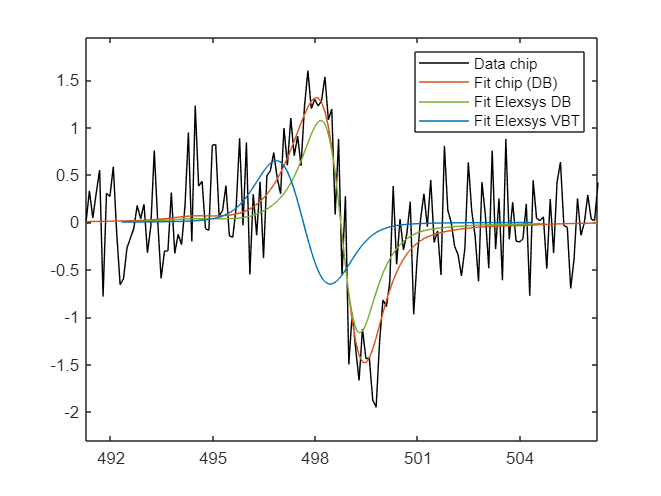



figure()
plot(x, y, x, scaleY(cumtrapz(y), y))
[~, id] = max(cumtrapz(y))

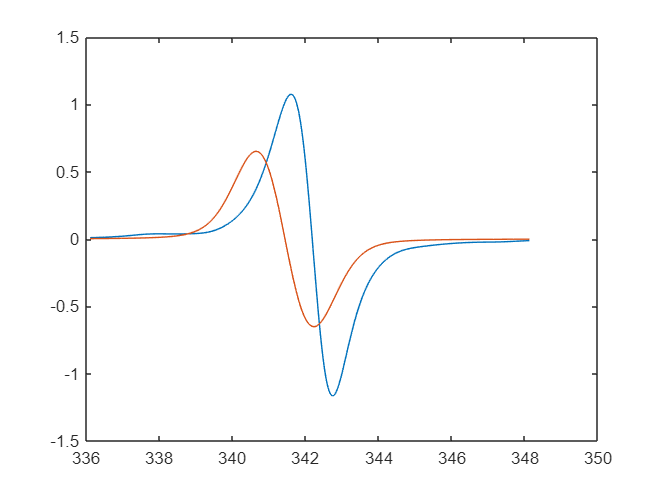

xline(x(id))
hold on
xnew = x(id:end);
ynew = cumtrapz(y(1:id));
ynewnew = flip(ynew);


plot(xnew, scaleY(ynewnew, y))

Exp.Range = [min(x) max(x)];
Sys = SysDb;
Vary = VaryDb;
Fit1comp = esfit(y, @pepper, {Sys, Exp}, {Vary});

[~, iMax] = max(Fit1comp.fit);
[~, iMin] = min(Fit1comp.fit);
Lwpp = x(iMin) - x(iMax)
